*Предмет: Практическая линейная алгебра*

*Автор: Made by Polyakov Anton, the part of R3236, suir family*

*Преподаватель: Алексей Алексеевич Перегудин*

[Source matlab code](https://github.com/GreedlyCore/practice_linear_algebra_labs)

## Шифр Хилла

Возьмем в качестве алфавита = русский алфавит и пробел:

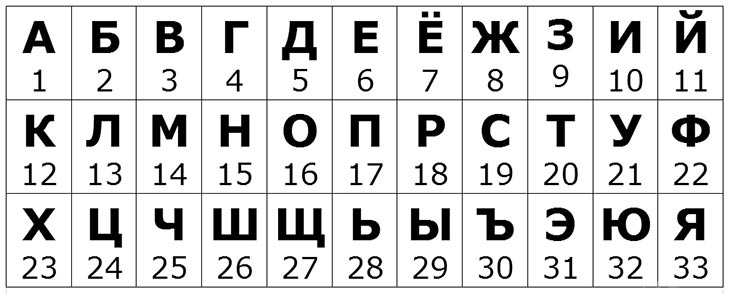

abc = ['А', 'Б', 'В', 'Г', 'Д', 'Е', 'Ё', 'Ж', 'З', 'И', 'Й', 'К', 'Л', 'М', 'Н', 'О', 'П', ...
    'Р', 'С', 'Т', 'У', 'Ф', 'Х', 'Ц', 'Ч', 'Ш', 'Щ', 'Ъ', 'Ы', 'Ь', 'Э', 'Ю', 'Я', ' '];
n = length(abc)

n = 34

msg = 'Я ЯБЛОКО СОК'

msg = 'Я ЯБЛОКО СОК'

m = length(msg)

m = 12

#### Генерируем ключи

Генерируем матрицу N*N со случайными целыми числами в диапазоне a...b

% key4= randi([1 100],4,4);
% det(key4);

Не иметь общих делителей <=> НОД == +-1

% if gcd(det(key4),length(abc)) == 1
%     key4
% end

Сделав пару итераций программы под разные размерности, выпишем матрицы...

key3 = [68 47 64;
        1 78 37;
        8 82 89];

key2 = [33, 95;
        73, 10];

key4 = [28 1 3 80;
        60 57 69 25;
        29 37 56 20;
        92 38 77 37];

### **Как работает алгоритм в случае ключей 3*3?**

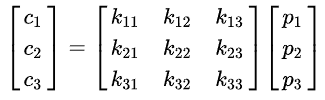

P -  векторы-столбцы исходный текст (open)

С - векторы-столбцы зашифрованный текст (closed)

K - key - ключ-матрица шифрования

Операции выполняем по модулю n=3

Чтобы расшифровать, надо получить обратную матрицу ключа:

inv_K = K^-1 **(mod n)**

Тогда.....

**Шифрование:** С = K*P (mod n)

**Расшифрование:** P= inv_K * C(mod n)

### Работа с матрицей 2x2

#### Шифрование

string_vector_1 = [33, 33, 13, 12, 34, 16;
                   34, 2, 16, 16, 19, 12];

% Посчитаем первый элемент
two_letters_vector = string_vector_1(:,1);
encrypted_string = '';
encryped_vector = mod(key2*two_letters_vector, n); 
encryped_vector = transpose(encryped_vector);
encrypted_string= append(encrypted_string,abc(encryped_vector(1)));
encrypted_string= append(encrypted_string,abc(encryped_vector(2)));

for i=2:size(string_vector_1, 2)
 two_letters_vector = string_vector_1(:,i);
 encryped_vector = mod(key2*two_letters_vector, n);
 for j=1:size(encryped_vector,1)
     encrypted_string= append(encrypted_string,abc(encryped_vector(j)));
 end
end
encrypted_string

encrypted_string = 'АЫУНЙУКОВТБЬ'

#### Вмешательство from hackerman

Чтобы убедиться, что матрицы расшифровываются правильно, можно закомментировать блок с вмешательством

% Выбранные индексы могут стать одинаковыми, это небольшая беда -__-
chosen_index = randi([1,12],1,3)

chosen_index =      9     6    12


chosen_symbol = randi([1,34],1,3)

chosen_symbol =     10     9     1


for i=1:3
    encrypted_string(chosen_index(i)) = abc(chosen_symbol(i));
end
encrypted_string

encrypted_string = 'АЫУНЙЗКОИТБА'

#### Расшифрование

inv_key2 = inverse_module_matrix(key2, n);
decrypted_string = '';
c = 1;
while c < m
    letter_code1 = strfind(abc, encrypted_string(c));
    letter_code2 = strfind(abc, encrypted_string(c+1));
    new_encrypted_vector = [letter_code1;letter_code2];
    decrypted_vector = mod((inv_key2*new_encrypted_vector),n);
    
    for j=1:size(decrypted_vector,1)
        if decrypted_vector(j) == 0
            % Отдельная проверка для нулей потому что 0 --> 34 = ' ' в моем
            % алфавите, но матлаба индексы начинаются с 1 ...
            decrypted_string= append(decrypted_string,abc(n));
        else 
            decrypted_string= append(decrypted_string,abc(int16(decrypted_vector(j))));
        end
    end
    c = c + 2;
end
decrypted_string

decrypted_string = 'Я ЯБЙШКОЬГЭД'

### Работа с матрицей 3x3

В этом и последующем блоке код копируется, увеличивается лишь размерность матриц. Также можно заметить, что при больших размерностях от оригинального сообщения остается (почти) ничего после хакера

#### Шифрование

string_vector_2 = [33,2,12,19;
                   34, 13,16,16;
                   33,16,34,12];

three_letters_vector = string_vector_2(:,1);
encrypted_string = '';
encryped_vector = mod(key3*three_letters_vector, n); 
encryped_vector = transpose(encryped_vector);
encrypted_string= append(encrypted_string,abc(encryped_vector(1)));
encrypted_string= append(encrypted_string,abc(encryped_vector(2)));
encrypted_string= append(encrypted_string,abc(encryped_vector(3)));

for i=2:size(string_vector_2, 2)
 three_letters_vector = string_vector_2(:,i);
 encryped_vector = mod(key3*three_letters_vector, n);
 for j=1:size(encryped_vector,1)
     encrypted_string= append(encrypted_string,abc(encryped_vector(j)));
 end
end

encrypted_string

encrypted_string = 'ГЬДВИЦГБМЦЙО'

#### Вмешательство from hackerman

chosen_index = randi([1,12],1,3)

chosen_index =      8     6     6


chosen_symbol = randi([1,34],1,3)

chosen_symbol =     32    15    15


encrypted_string

encrypted_string = 'ГЬДВИЦГБМЦЙО'

for i=1:3
    encrypted_string(chosen_index(i)) = abc(chosen_symbol(i));
end
encrypted_string

encrypted_string = 'ГЬДВИНГЮМЦЙО'

#### Расшифрование

inv_key3 = inverse_module_matrix(key3,n);
decrypted_string = '';
c = 1;
while c < m
    new_encrypted_vector = [strfind(abc, encrypted_string(c));
                           strfind(abc, encrypted_string(c+1));
                           strfind(abc, encrypted_string(c+2))];
    decrypted_vector = round(mod((inv_key3*new_encrypted_vector),n));
    
    for j=1:size(decrypted_vector,1)
        if decrypted_vector(j) == 0
            decrypted_string= append(decrypted_string,abc(n));
        else 
            decrypted_string= append(decrypted_string,abc(int16(decrypted_vector(j))));
        end
    end
    c = c + 3;
end
decrypted_string       

decrypted_string = 'Я ЯААЙГБМСОК'

### Работа с матрицей 4x4

#### Шифрование

string_vector_3 = [33 13 34;
                   34 16 19;
                   33 12 16;
                   2 16 12];

four_letters_vector = string_vector_3(:,1);
encrypted_string = '';
encryped_vector = mod(key4*four_letters_vector, n); 
encryped_vector = transpose(encryped_vector)

encryped_vector =     27    23    23     7


encrypted_string= append(encrypted_string,abc(encryped_vector(1)));
encrypted_string= append(encrypted_string,abc(encryped_vector(2)));
encrypted_string= append(encrypted_string,abc(encryped_vector(3)));
encrypted_string= append(encrypted_string,abc(encryped_vector(4)));

for i=2:size(string_vector_3, 2)
 four_letters_vector = string_vector_3(:,i);
 encryped_vector = mod(key4*four_letters_vector, n);
 for j=1:size(encryped_vector,1)
     encrypted_string= append(encrypted_string,abc(encryped_vector(j)));
 end
end

encrypted_string

encrypted_string = 'ЩХХЁЬЬХФЁДВР'

#### Вмешательство from hackerman

chosen_index = randi([1,12],1,3)

chosen_index =      5     3    12


chosen_symbol = randi([1,34],1,3)

chosen_symbol =      7    28    25


encrypted_string

encrypted_string = 'ЩХХЁЬЬХФЁДВР'

for i=1:3
    encrypted_string(chosen_index(i)) = abc(chosen_symbol(i));
end
encrypted_string

encrypted_string = 'ЩХЪЁЁЬХФЁДВЧ'

#### Расшифрование

inv_key4 = inverse_module_matrix(key4,n);
decrypted_string = '';
c = 1;
while c < m
    new_encrypted_vector = [strfind(abc, encrypted_string(c));
                           strfind(abc, encrypted_string(c+1));
                           strfind(abc, encrypted_string(c+2));
                           strfind(abc, encrypted_string(c+3))];
    decrypted_vector = round(mod((inv_key4*new_encrypted_vector),n));
    
    for j=1:size(decrypted_vector,1)
        if decrypted_vector(j) == 0
            decrypted_string= append(decrypted_string,abc(n));
        else 
            decrypted_string= append(decrypted_string,abc(int16(decrypted_vector(j))));
        end
    end
    c = c + 4;
end
decrypted_string

decrypted_string = 'ФЪЙЪЭЦЁАЯИХБ'

### Вспомогательные функции и их описание

#### Обратная матрица по модулю

function result = inverse_module_matrix(matrix, modulus)
    base = det(matrix);
    inv_element = 1;
    
    if gcd(base, modulus) ~= 1
        disp("Solution not found.")
    else
        for i = 1: modulus
            if mod(base * i, modulus) == 1
                inv_element = base*i;
                break;
            end
        end
    end
    result = mod((inv_element*(matrix^-1)),modulus);
end